clc
clear
% Prova Kalman Filter 

% Modello
% x[n + 1] = Ax[n] + Bu[n] + Gw[n]
% y[n] = Cx[n] + Du[n] + Hw[n] + v[n]

A =  [1 0;1 1]; % valori paper: A = eye(2);

B = [1;0.5]; % valori paper: B = 0;

C = eye(2);  % valori paper: C = [cos(), -sin()];

D = 0;

Q = eye(2); % process noise covariance
R = eye(2); % meas noise covariance
W = eye(2);
U = 1;
n = 2; %dim x
m = 2; %dim y
P = 0; %error covariance
S = 0;

%[P,L,G] = dare(A,B,Q,R) 
% computes the unique stabilizing solution X of the discrete-time algebraic Riccati equation
% The dare function also returns the gain matrix, G and the vector L of closed loop eigenvalues, where
% G = (C'PC+R)^-1 C'PA and L = eigen(A-C*G, E)


%kalman filter
%error prediction cov P(t|t-1)= A
%error  cov P(t)= 

[preP,~,~] = dare(A',C',Q,R);  
[P,~,L] = dare(A,B,W,U);
L = -L;
K = P*C'*inv(C*P*C'+R); %kalman gain

eig(A)

ans =      1
     1


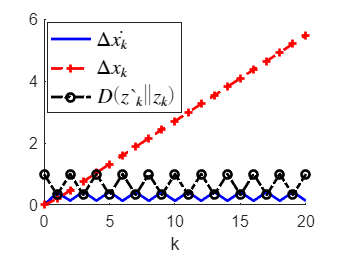

cP = C*P*C' + R;
invcP = inv(cP);

Gamma = diag([0,1]);

% v is an unstable eigenvector for A
% the corresponding eigenvalue is 1
% Cv is in the span of Gamma
v = [0;1];
lambda = 1;

% calculate the attacker's input to reach v
Co = -[(A-K*C*A)*K*Gamma K*Gamma];;

ya = Co\v;
% reshape ya from [ya(0);ya(1)] to [ya(0),ya(1)]
ya = reshape(ya,m,[]);

e(:,1) = -K*Gamma*ya(:,1);
z(:,1) = Gamma*ya(:,1);

e(:,2) = (A-K*C*A)*e(:,1)-K*Gamma*ya(:,2);
z(:,2) = C*A*e(:,1) + Gamma*ya(:,2);

M = max(norm(z(:,1)),norm(z(:,2)));

ya = ya/M;

%easy to verify that Gamma ystar = Cv
ystar = C*v;


for i = 3:31
    ya(:,i) = ya(:,i-2) - lambda^(i-2)/M*ystar;
end

e(:,1) = -K*Gamma*ya(:,1);
z(:,1) = Gamma*ya(:,1);
for i=2:21
    e(:,i) = (A-K*C*A) * e(:,i-1) - K*Gamma * ya(:,i);
    z(:,i) = C*A * e(:,i-1) + Gamma * ya(:,i);
end


for i = 1:21
    normz(i) = norm(z(:,i));
end

hatx(:,1) = K*z(:,1);
for i = 2:21
    hatx(:,i) = (A+B*L)*hatx(:,i-1)+K*z(:,i);
end
x = hatx + e;

figure(1)
hold on
plot(0:20,x(1,:),'b-','Linewidth',2);
plot(0:20,x(2,:),'r+--','Linewidth',2);
plot(0:20,normz,'ko-.','Linewidth',2);
legend('$\Delta \dot{x_k}$', '$\Delta x_k$', '$D(z`_k\|z_k)$','location','best');
h = legend;
set(h, 'interpreter', 'latex','fontsize',16)
xlabel('k','fontsize',12);
h = gca;
set(h,'Fontsize',12);
hold off

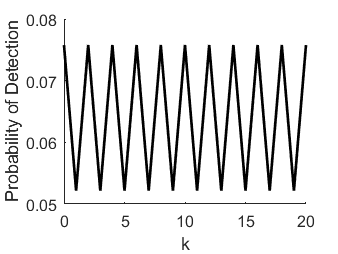



thre = chi2inv(0.95,m);
for i = 1:21
    %g_k follow a non-central chi^2 distribution
    detectionprob(i) = 1 - ncx2cdf(thre, m, z(:,i)'*invcP*z(:,i));
end

figure(2)
hold on
plot(0:20,detectionprob,'k','Linewidth',2);

xlabel('k','fontsize',12);
ylabel('Probability of Detection','fontsize',12);
h = gca;
set(h,'Fontsize',12);
hold off